# Simulating Transistor Quiz Question 5

8 April 23 B.R.

Questions are based on this circuit, hfe = beta = 100. Assume Vbe = .6V when the transistor is on, and the blue LED has Vf=2V.

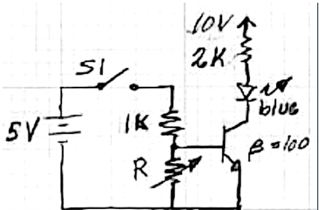

Question 5: With S1 closed, as R changes from 1kohm down to 100ohms, the LED will: __ brighten, __ dim, __ turn off, __ stay the same brightness?

Here's a simulation. First think of R and 1k as voltage dividers assuming the transistor is OFF, $Z_{BE} = \infty$ which is reasonably accurate for Vb << 0.5V. But once the transistor turns on, its base -emitter diode in parallel with R "shorts out" the voltage divider, keeping the voltage across R at 0.6V. 

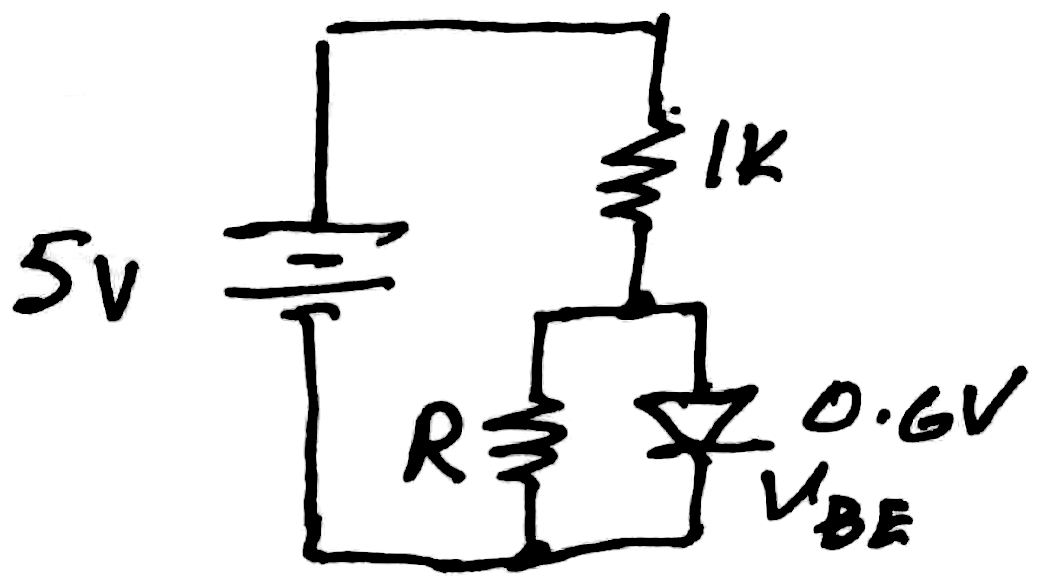

Equivalent base emitter circuit with switch closed and transistor ON (active or saturated). Collector-emitter circuit not shown for simplicity.

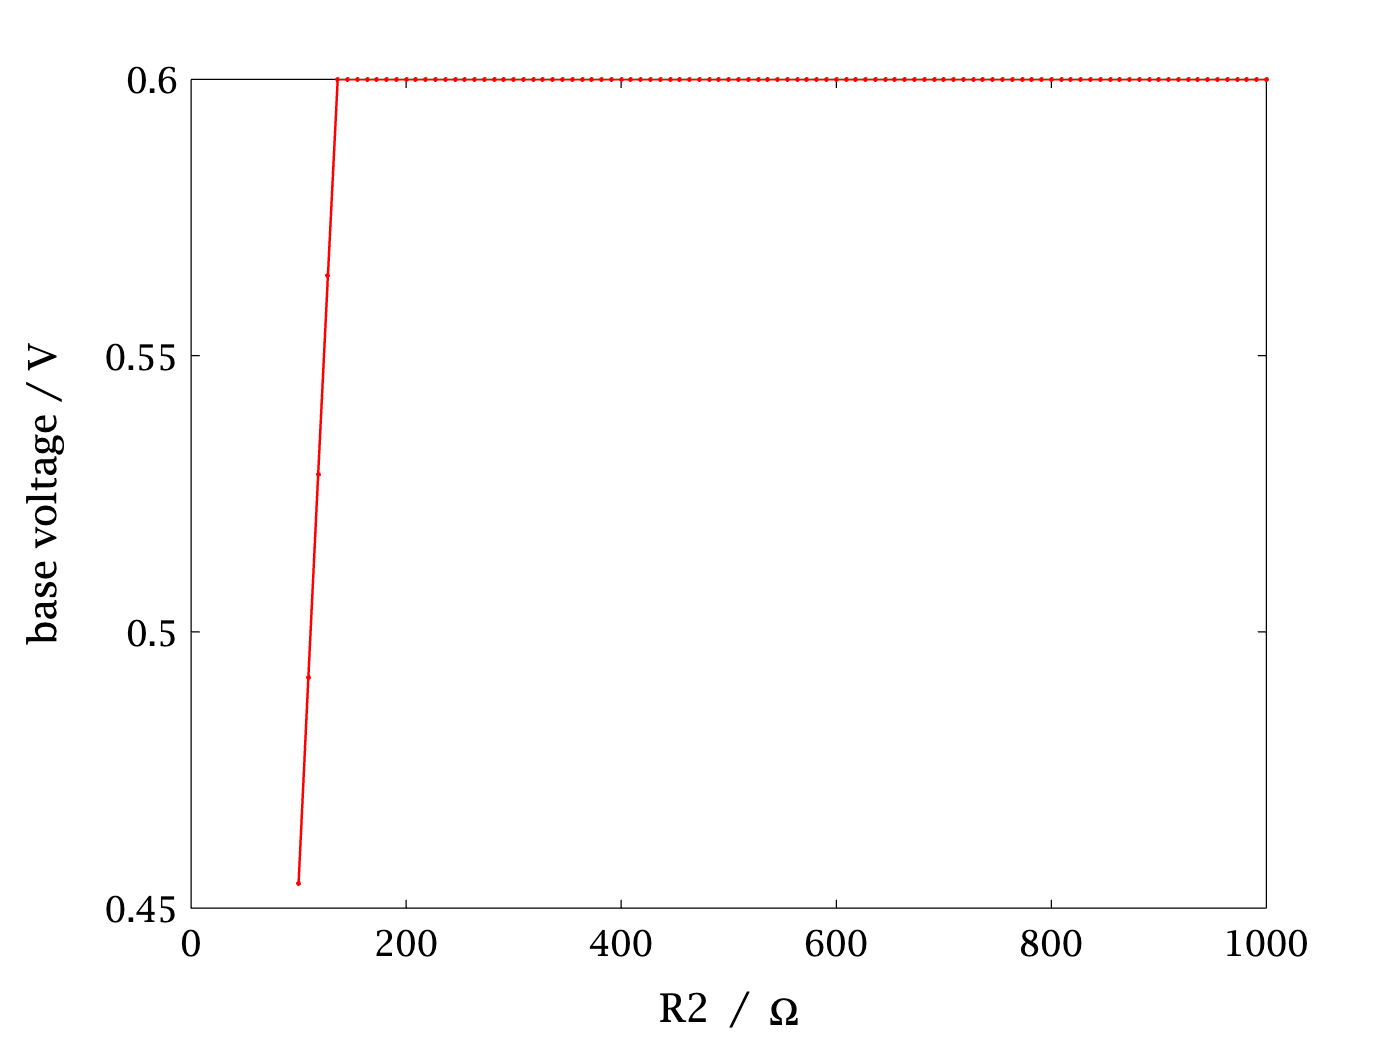

Vin = 5;
R1 = 1e3; % naming 1k resistor
Rvar = linspace(100,1e3)'; % (R in the schematic)
Vb = Vin * Rvar ./ (R1+Rvar); % if no transistor
Vb(Vb > 0.6) = 0.6; % diode "clamp"
plot(Rvar, Vb,'.-'); xlabel('Rvar / \Omega'); ylabel('base voltage / V')

grid;

Compute the currents with Ohm's Law, 

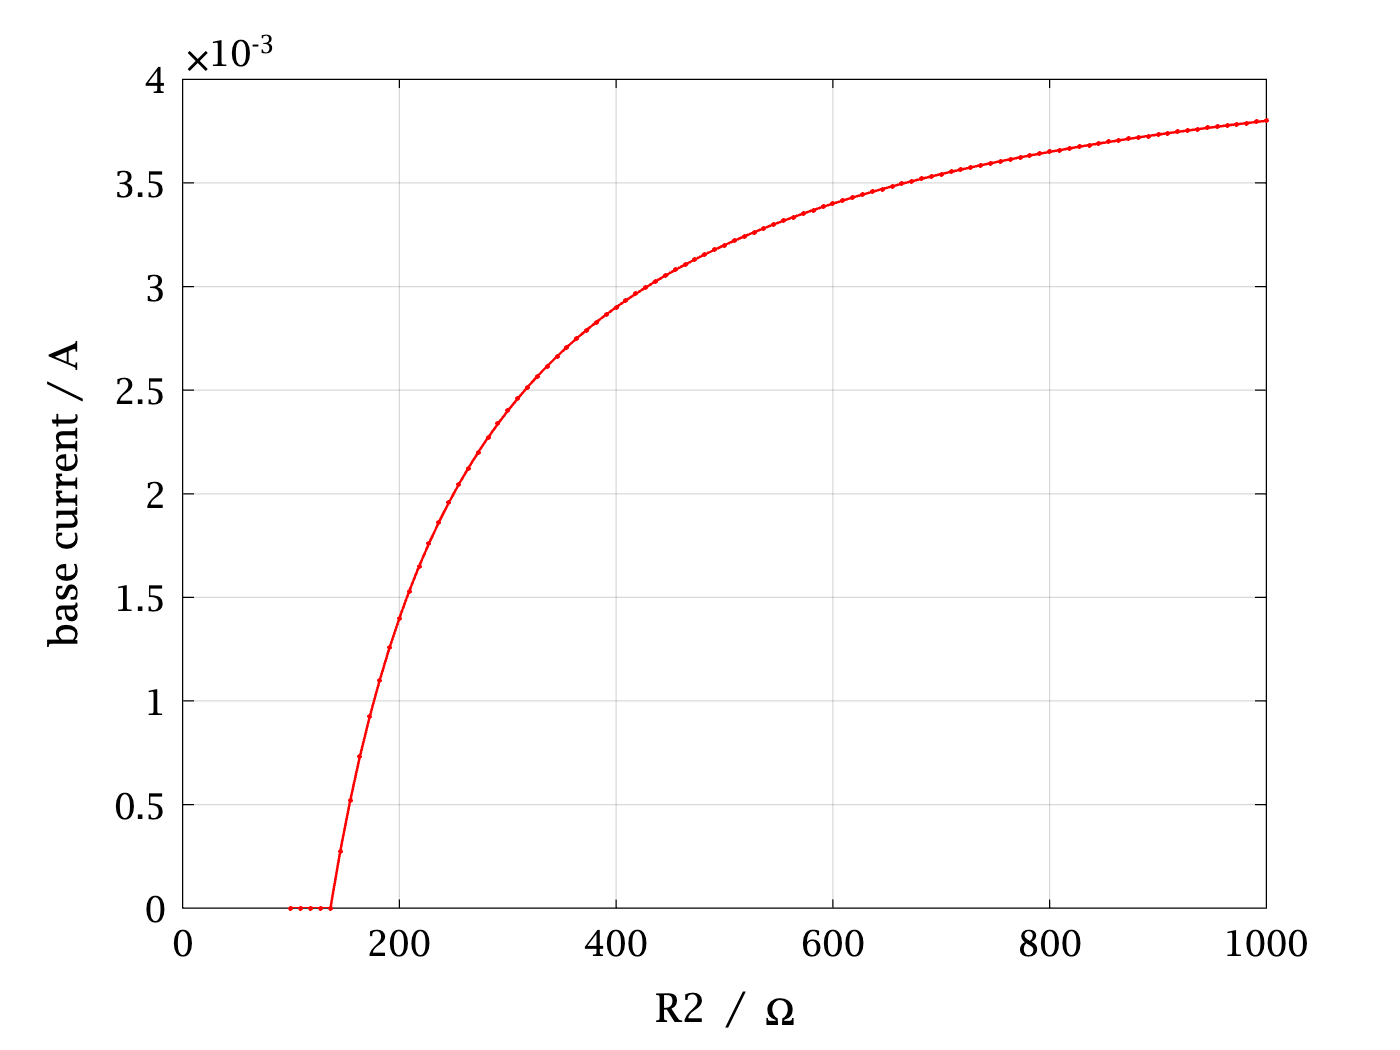

i1 = (Vin - Vb) / R1; % Ohm's Law
ivar = Vb ./ Rvar; % Ohm's Law for Rvar
ib = i1-ivar; % KCL -- R1 current has 2 possible paths
plot(Rvar, ib,'.-'); grid;
xlabel('Rvar / \Omega'); ylabel('base current / A')

As Rvar gets larger ("resists more"), more current flows through the base. "Current takes the path of least resistance", and $Z_{BE}$ is a low resistance path once the base-emitter diode is forward biased. Now let's look at the output side of the transistor. The collector current could be $\beta = 100$ times greater than $i_{base}$ above, until it saturates. Saturation happens when $Z_{CE} \rightarrow 0 \Omega$, the equivalent circuit is 10V in series with $2K\Omega$ and $V_f = 2V$ of the LED. KVL says $10V + V_{2k} + V_f + V_{CE}= 0$ and in saturation $V_{CE}\rightarrow 0$ so $V_{2k} = 10-V_f = 8V%$in saturation, and Ohm's Law gives the maximum saturation current. 

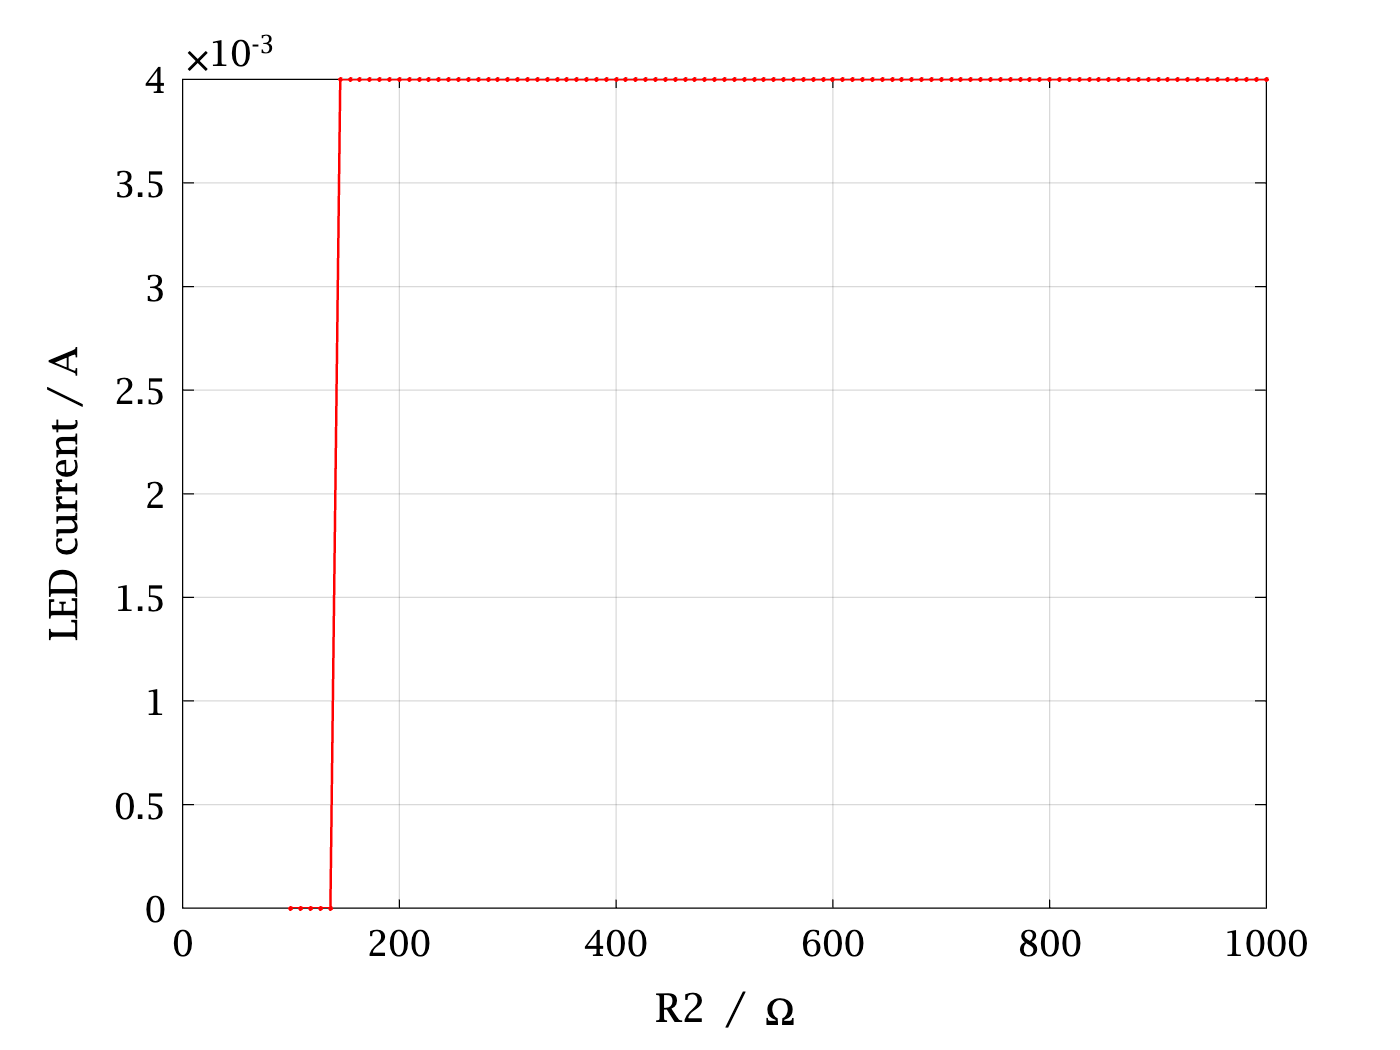

beta = 100;
ic = beta * ib; % in the transistor active region
icsat = (10-2)/2e3; % saturation current
ic(ic>icsat) = icsat;
plot(Rvar, ic,'.-'); grid;
xlabel('R2 / \Omega'); ylabel('LED current / A')

A key point is the saturation current is a *circuit* property, not an intrinsic transistor property, like $\beta$ is. For the ylabel, I made the inference that the collector current is the LED current. You can see why we call this circuit a switch. Although the base current takes on a range of values, the LED current jumps, here a few of the discrete values near the corner or "knee":

fprintf('%1.2E\t',ic(4:7))

0.00E+00	8.67E-17	4.00E-03	4.00E-03	

fprintf('%1.2E\t',Rvar(4:7))

1.27E+02	1.36E+02	1.45E+02	1.55E+02	

 Current is <1e-16A at R2 = 136 ohms, and saturated at 4mA at R2 = 145 ohms. 

### Ebers-Moll Transistor Model

According to our model above, the LED would turn OFF for R < ~140 ohms. Is the model right?? We have ample reason to doubt it because we shouldn't expect a "piecewise linear" model to accurately model the transistor's behavior at its corner. Let's see if we can apply a better model, and we can find the equations at [https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Large-signal_models](https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Large-signal_models):

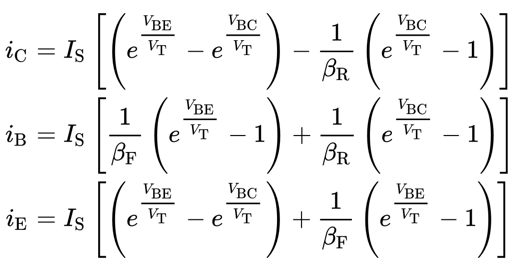

Ooohh, you should be saying, a "much better model -- why didn't we start with this?" /s. These "Ebers-Moll" equations introduce lots of parameters. Some are approximate constants given on the Wikipedia page, but some are uncertain over orders of magnitude (like $I_s$ = 1e-15 to 1e-12), and some depend on the (dynamic) state of the circuit. A good approach is to restrict the domain that we're trying to model, e.g., just to around the knee when the transistor is turning on, Vbe <~ .6V. (Fun fact: if you take the 0.6V limit off of Vb, you'll get ib and ic approaching 10^30A -- *slightly* unrealistic.) I'm not sure how to handle$V_{BC}$, because when the transistor is off, $V_{BC}$ is large. KVL says 10V-ic * 2k - $V_{LED}$ - $V_{BC}$ = 0, but ic isn't known let (it's one of the above equations that depends on $V_{BC}$, and we're not sure the LED has reached it's knee voltage yet -- that depends on ic. So there are multiple coupled equations to solve ... So try the easiest guess: $V_{BC}$ << $V_{BE}$ = Vb, and ignore it ;-). 

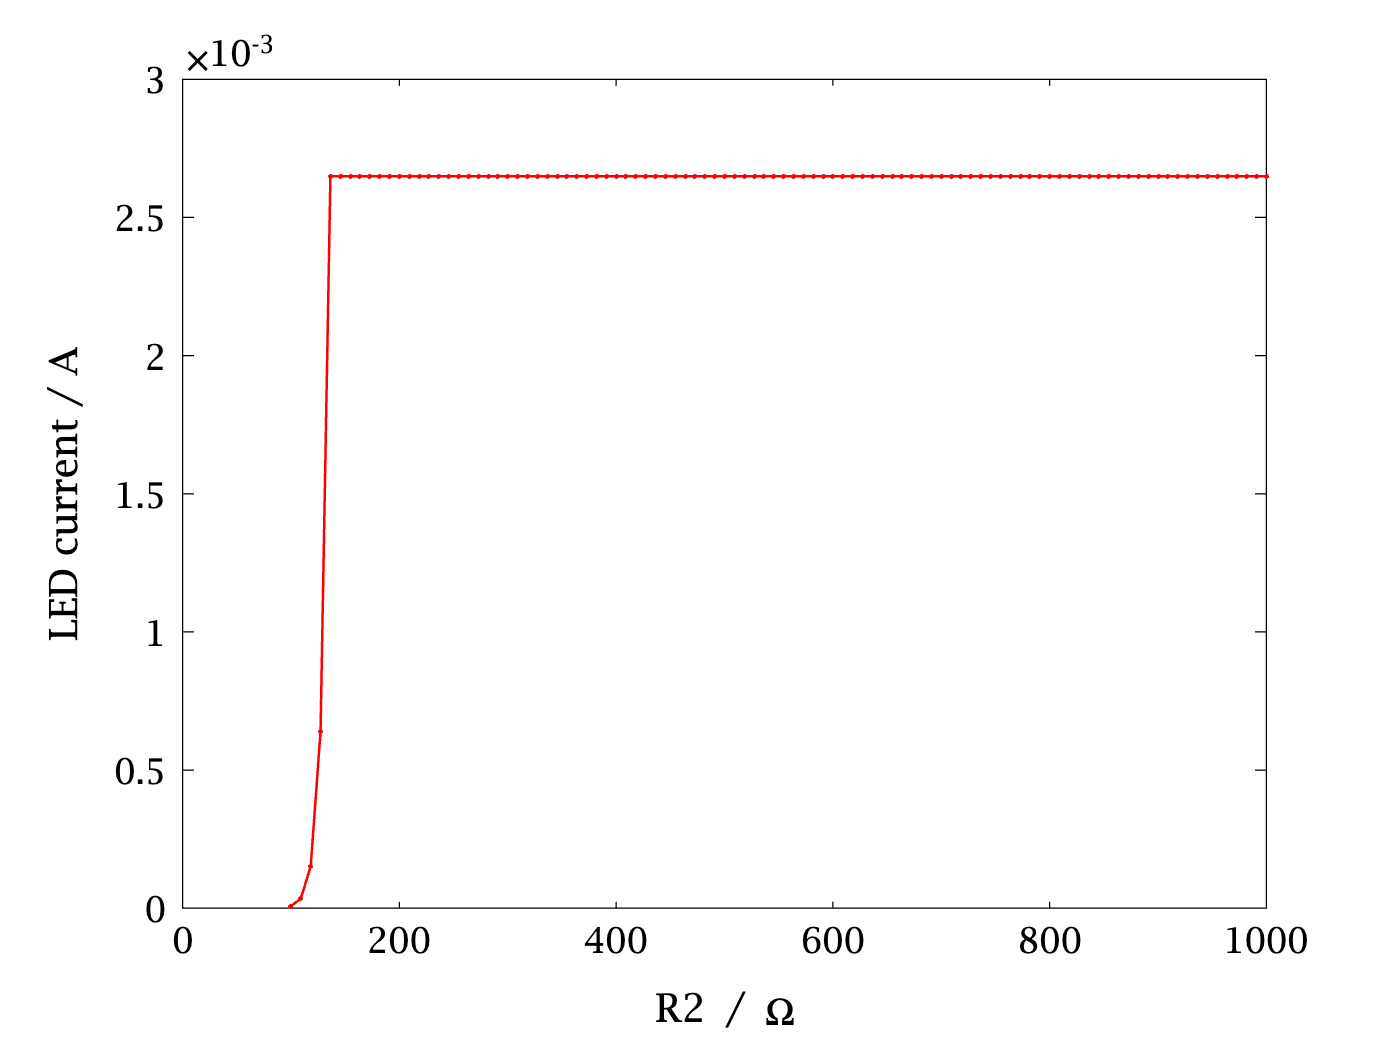

Vt = 25e-3; % thermal voltage of a transistor
bf = beta;
br = beta/10; % wild guess of reverse common emitter gain
Is = 1e-13; % 1e-15 to 1e-12, reverse saturation current
ibem = Is * [1/bf * (exp(Vb/Vt) - 1)];
icem = Is * (exp(Vb/Vt));
plot(Rvar, icem, '.-');
xlabel('R2 / \Omega'); ylabel('LED current / A')

The saturation current is a little low -- which we could fix by increasing Is (by the ratio of the right answer / wrong answer ~ 4/2.6). But Ebers-Moll predicts a more gradual turn-on at the lowest R2 values. If we `set(gca,'yscale','log')` or just replot this on a log scale: 

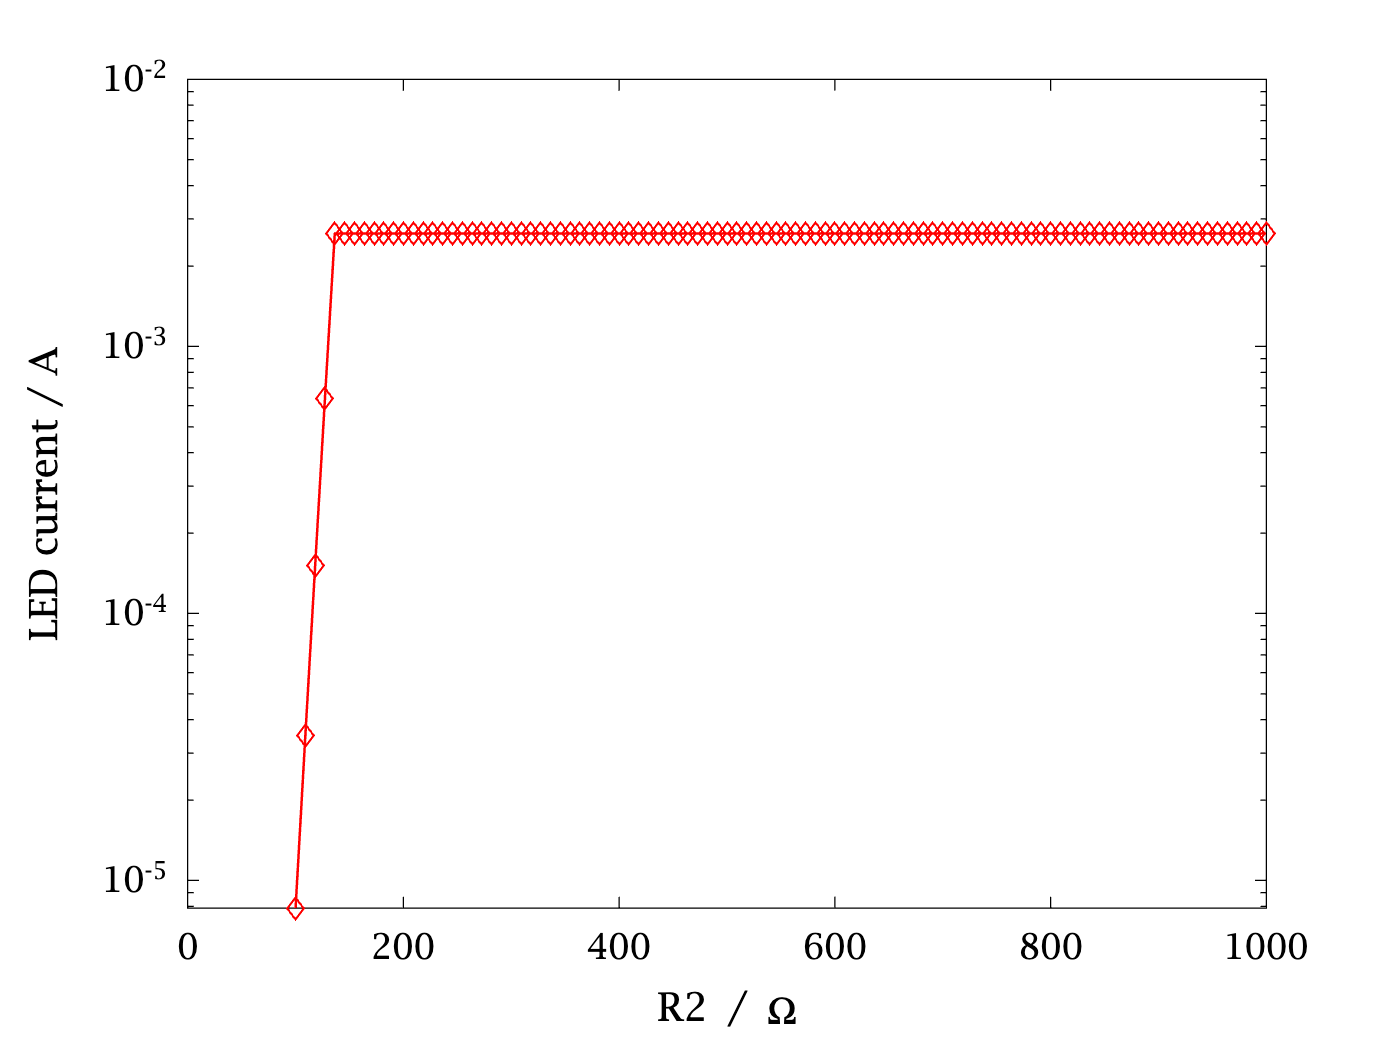

semilogy(Rvar, icem,'d-')
xlabel('R2 / \Omega'); ylabel('LED current / A')

It predicts the LED *would* be vastly dimmer at R2 = 100 ohms, but technically not off -- with LED current ~ 8$\mu$A. Not clear if that's bright enough to see, but more importantly, not clear that we should have more confidence in this prediction's numerical value than the prior model, for the same reasons -- there are just too many *ad hoc* assumptions in the model.

We could attempt to build the circuit on the breadboard -- but that's actually not easy unless you can find an NPN transistor with $\beta$ = 100 ... but we could build it with our 2N2222 transistor with around twice that beta. We can make some predictions: if the LED is very dim, then it would be even dimmer with $\beta$ = 100. However, if it is off with $\beta$ = 200 then it would certainly be off with $\beta$ = 100. And, drum roll ... 

With Vref = 4.5V, R1=1k, R2 = 100 ohms, 10V -> 2k -> blue LED -> collector, the LED is OFF. Vb measured .42V ~ 4.5V * 100/(100+1k), as if the transistor were an infinite Z (left of the $V_{BE}$ knee). Replaced R2 with 200 ohms and  LED is full brightness, not visibly different than R2 = infinity, no voltage divider, ib = (4.5-.7V)/1k. The LED shuts off somewhere between R2 = 100-200 ohms. When it's off, $V_{BC}$ ~ 0.42-7.6V is large but *negative*, aaahhhhh so $e^{(V_{BC}/V_T)} \approx 0$ because the exponent is large *negative*, making the second parentheses of $i_C$ negligible compared to the first, and the 2nd term of the first parenthesis is negligible compared to the first, $e^{(V_{BE}/V_T)} \approx e^{.6/.026} \approx 10^{10}$. So that's why my guess to ignore $V_{BC}$ worked as well as it did. 

### Reflection

This is the first time I tried an Ebers-Moll model and it wasn't super illuminating nor useful, but you win some and you lose some ... 